# Missing Data Imputation using Statistical Methods

Reference: https://www.mathworks.com/help/matlab/ref/fillmissing.html

## Table of Contents:

- Data Generation

- Zero and NaN values

- fillmissing method

- Previous

- Next

- Nearest

- Linear

- Spline

- Pchip

- Makima

- movmean

- movmedian

### Dataset Generation

We will create a dummy data that contains time and power in megawatts.

Time = 1:1:1000;
x = linspace(0,6*pi,1000);
Power = 100*sin(x);

### Load Dataset

data = readtable('Dataset.xlsx'); %tablename
Time = data.Time;   %tablename.columnname (column name can be accessed by opening dataset/table)
Power = data.Power; %tablename.columnname

### Plot Time vs. Power

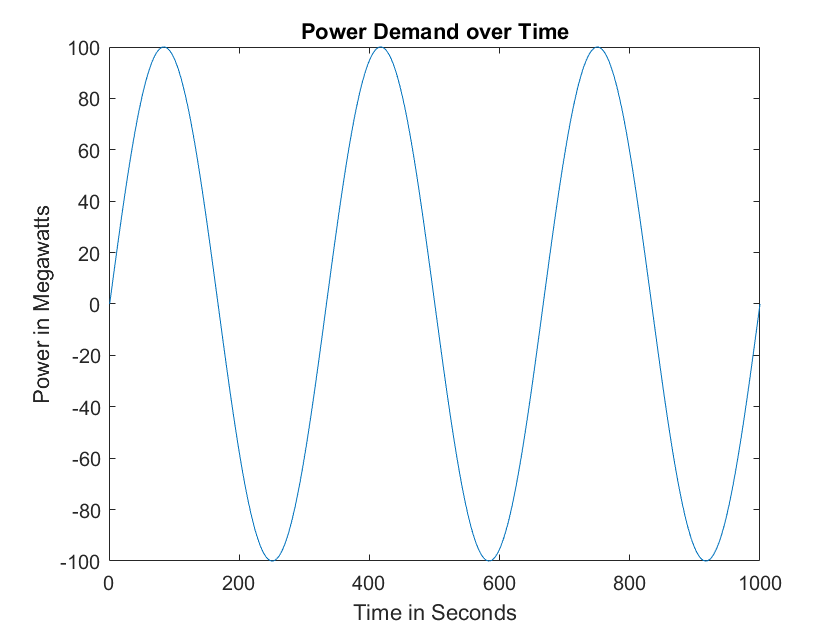

plot(Time, Power)
xlabel('Time in Seconds')
ylabel('Power in Megawatts')
title('Power Demand over Time')

### Zero and NaN Values

This section will how does zero and NaN look like in plot of power and time

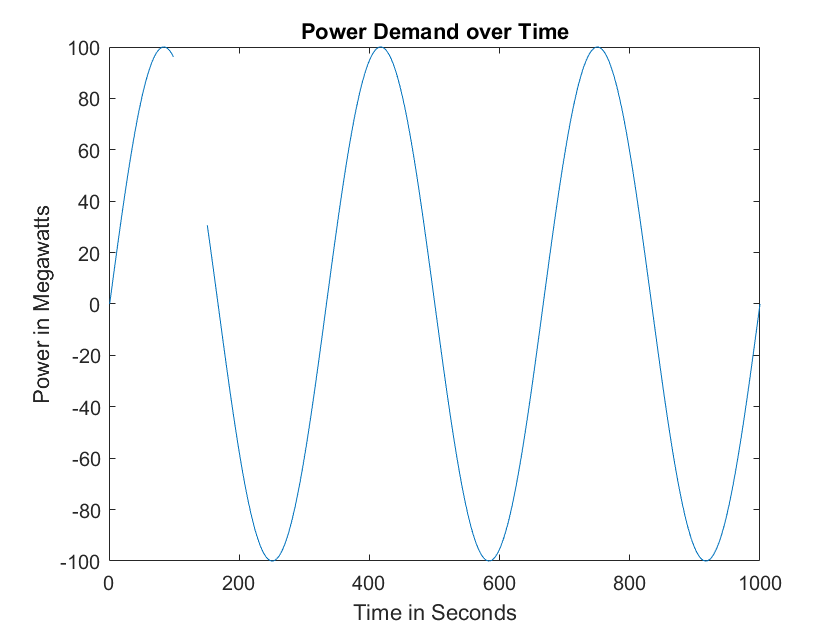

Power_nan = Power;
Power_nan(100:150) = NaN;
plot(Time, Power_nan)
xlabel('Time in Seconds')
ylabel('Power in Megawatts')
title('Power Demand over Time')

%This time, impute the missing values as 0
Power_zero = Power_nan;
Power_zero(isnan(Power_zero)) = 0;
rmse_zero = sqrt(mse(Power, Power_zero))

rmse_zero = 16.1919

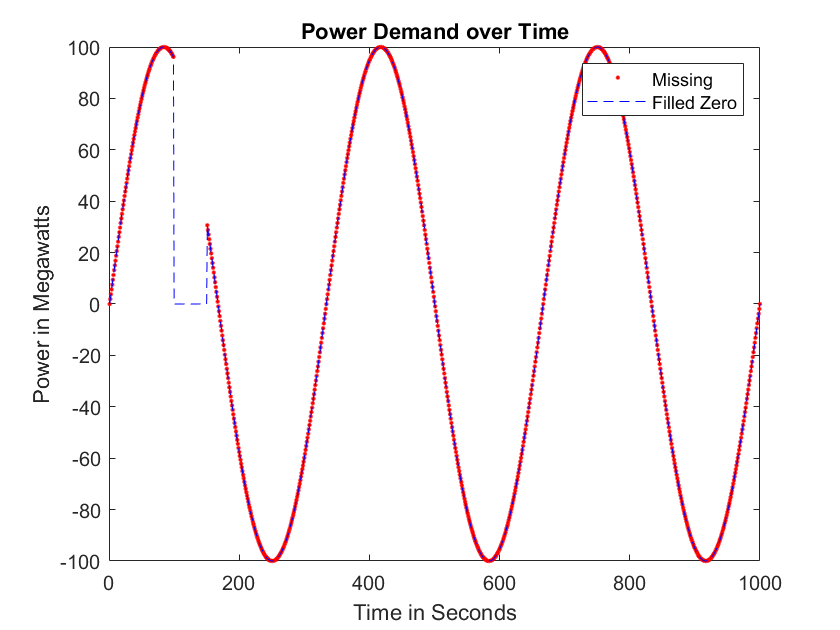

plot(Time, Power_nan, 'r.')
hold on
plot(Time, Power_zero, 'b--')
xlabel('Time in Seconds')
ylabel('Power in Megawatts')
title('Power Demand over Time')
legend('Missing', 'Filled Zero')
hold off

### fillmissing Function

This function allows us to impute missing data using different methods

**SYNTAX**

[`F = fillmissing(A,method)`](https://www.mathworks.com/help/matlab/ref/fillmissing.html#d122e390722)` %A is the data/table, method is the imputation`

### `Previous Method`

fill_previous = fillmissing(Power_nan, 'previous');
rmse_previous = sqrt(mse(Power, fill_previous))

rmse_previous = 7.4637

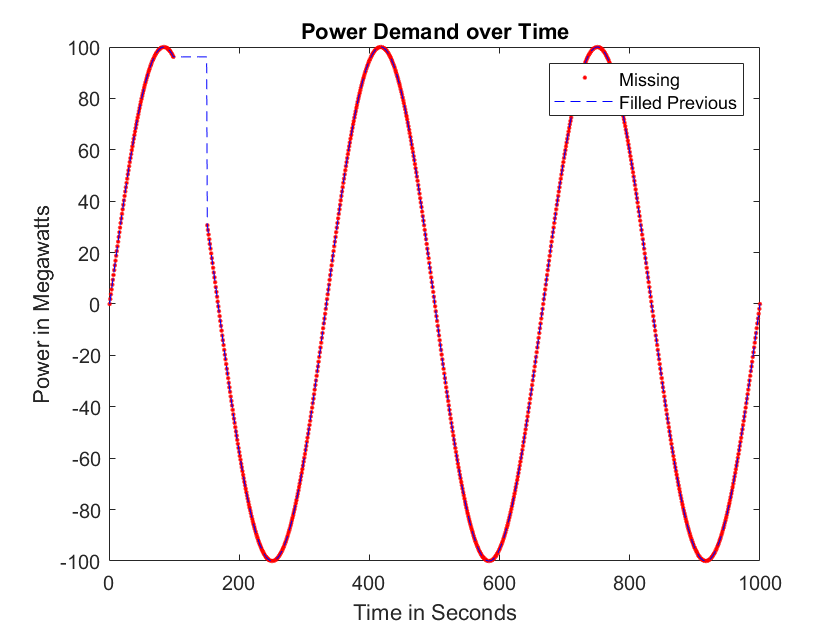

plot(Time, Power_nan, 'r.')
hold on
plot(Time, fill_previous, 'b--')
xlabel('Time in Seconds')
ylabel('Power in Megawatts')
title('Power Demand over Time')
legend('Missing', 'Filled Previous')
hold off

### Next Method

fill_next = fillmissing(Power_nan, 'next');
rmse_next = sqrt(mse(Power, fill_next))

rmse_next = 9.6975

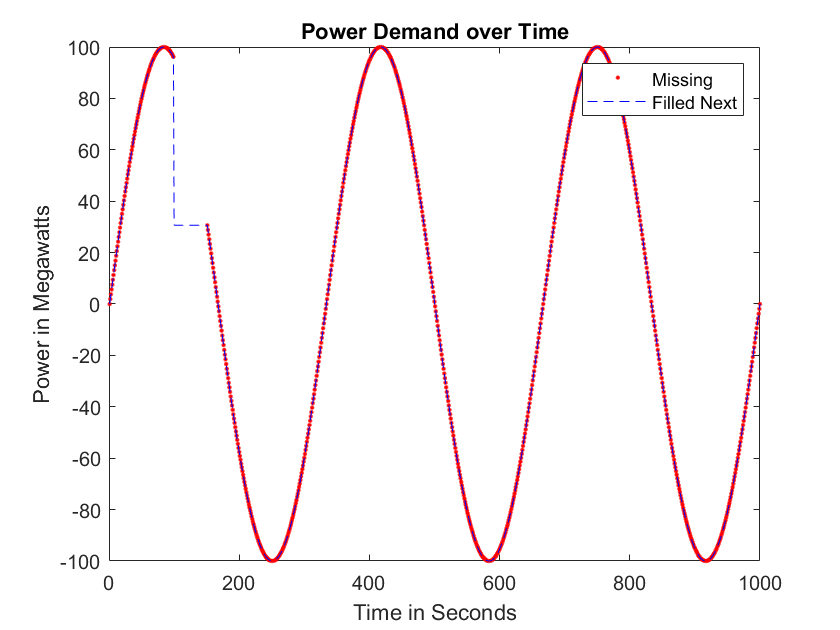

plot(Time, Power_nan, 'r.')
hold on
plot(Time, fill_next, 'b--')
xlabel('Time in Seconds')
ylabel('Power in Megawatts')
title('Power Demand over Time')
legend('Missing', 'Filled Next');
hold off

### Nearest Method

fill_nearest = fillmissing(Power_nan, 'nearest');
rmse_nearest = sqrt(mse(Power, fill_nearest))

rmse_nearest = 4.5414

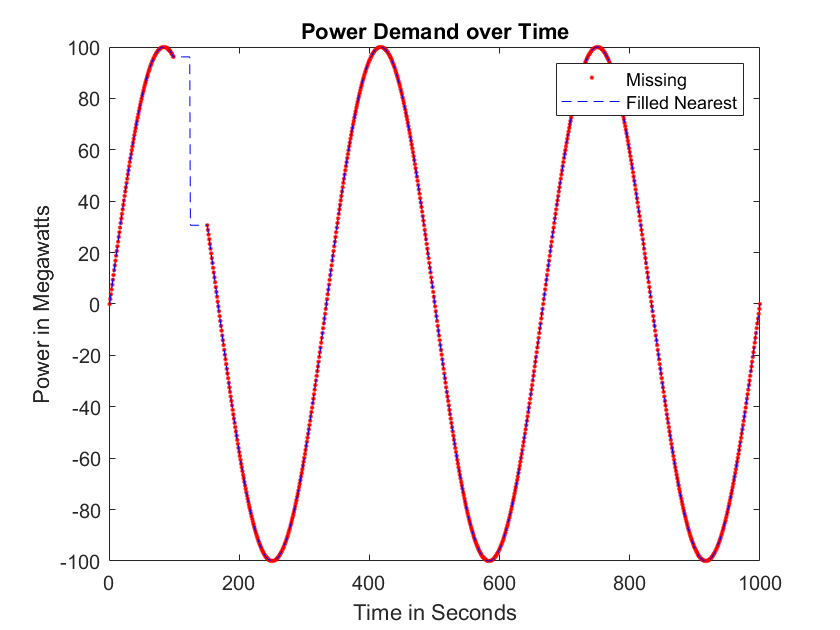

plot(Time, Power_nan, 'r.')
hold on
plot(Time, fill_nearest, 'b--')
xlabel('Time in Seconds')
ylabel('Power in Megawatts')
title('Power Demand over Time')
legend('Missing', 'Filled Nearest');
hold off

### Linear Method

fill_linear = fillmissing(Power_nan,'linear','SamplePoints',Time);
rmse_linear = sqrt(mse(Power, fill_linear))

rmse_linear = 1.4100

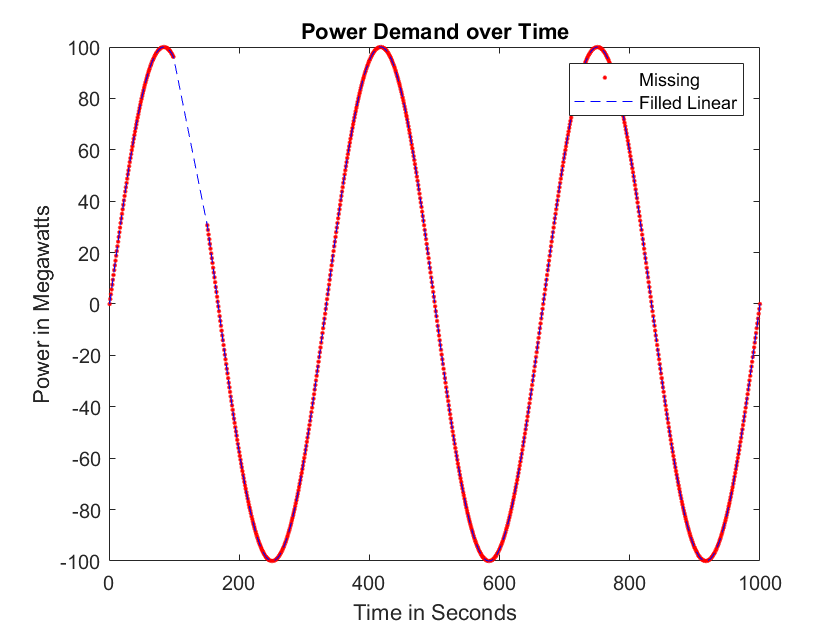

plot(Time, Power_nan, 'r.')
hold on
plot(Time, fill_linear, 'b--')
xlabel('Time in Seconds')
ylabel('Power in Megawatts')
title('Power Demand over Time')
legend('Missing', 'Filled Linear');
hold off

### Spline Method

fill_spline = fillmissing(Power_nan, 'spline');
rmse_spline = sqrt(mse(Power, fill_spline))

rmse_spline = 0.0260

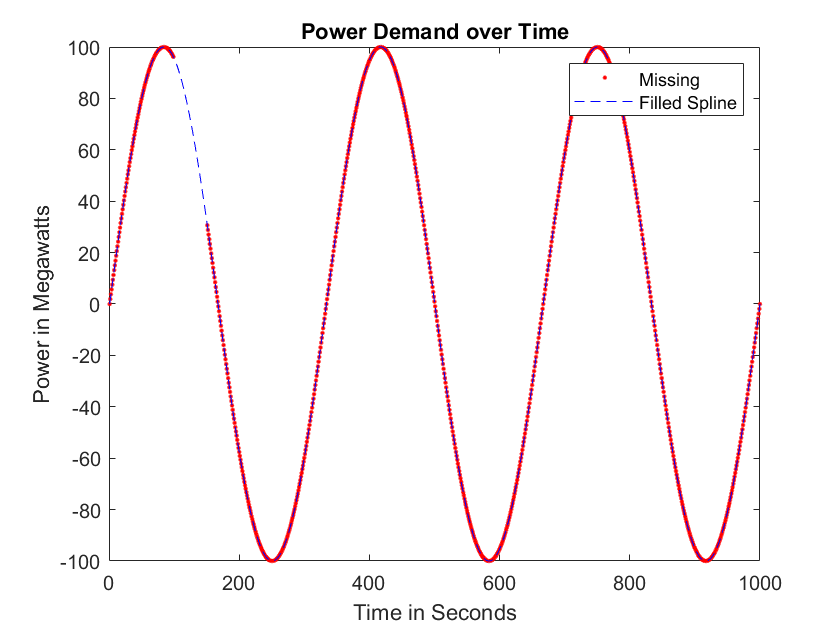

plot(Time, Power_nan, 'r.')
hold on
plot(Time, fill_spline, 'b--')
xlabel('Time in Seconds')
ylabel('Power in Megawatts')
title('Power Demand over Time')
legend('Missing', 'Filled Spline');
hold off

### Pchip Method

fill_pchip = fillmissing(Power_nan, 'pchip');
rmse_pchip = sqrt(mse(Power, fill_pchip))

rmse_pchip = 0.3905

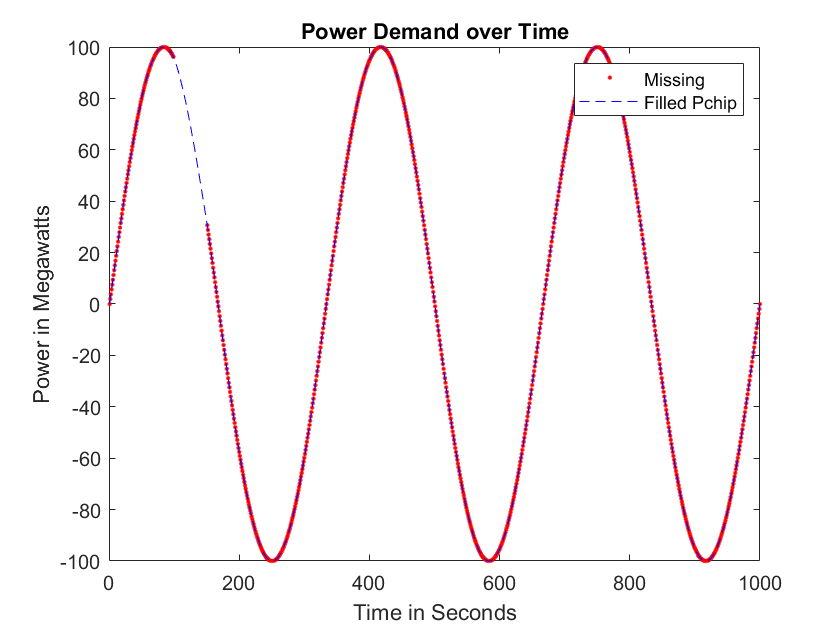

plot(Time, Power_nan, 'r.')
hold on
plot(Time, fill_pchip, 'b--')
xlabel('Time in Seconds')
ylabel('Power in Megawatts')
title('Power Demand over Time')
legend('Missing', 'Filled Pchip');
hold off

### Makima Method

fill_makima = fillmissing(Power_nan, 'makima');
rmse_makima = sqrt(mse(Power, fill_makima))

rmse_makima = 0.4761

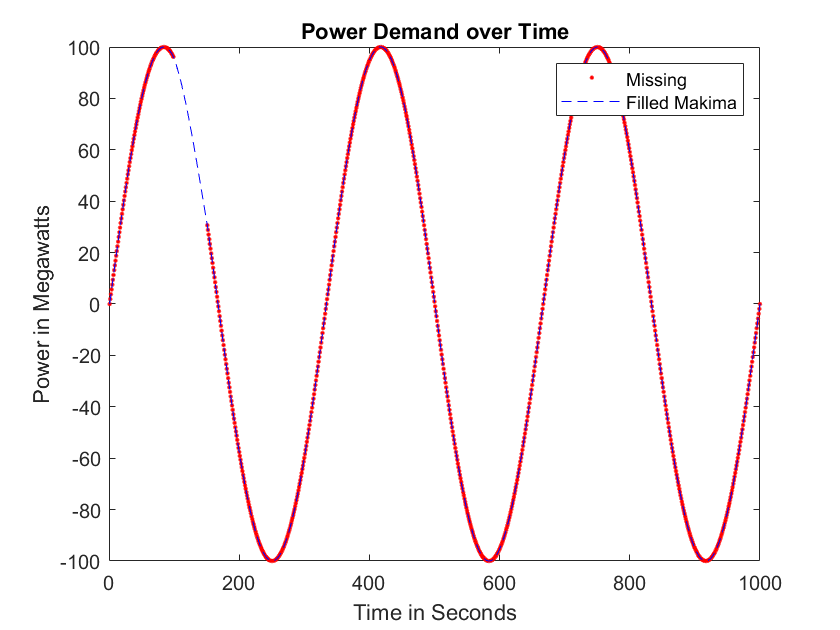

plot(Time, Power_nan, 'r.')
hold on
plot(Time, fill_makima, 'b--')
xlabel('Time in Seconds')
ylabel('Power in Megawatts')
title('Power Demand over Time')
legend('Missing', 'Filled Makima');
hold off

### Moving Mean

fill_movmean = fillmissing(Power_nan, 'movmean', 60);
rmse_movmean = sqrt(mse(Power, fill_movmean))

rmse_movmean = 5.7153

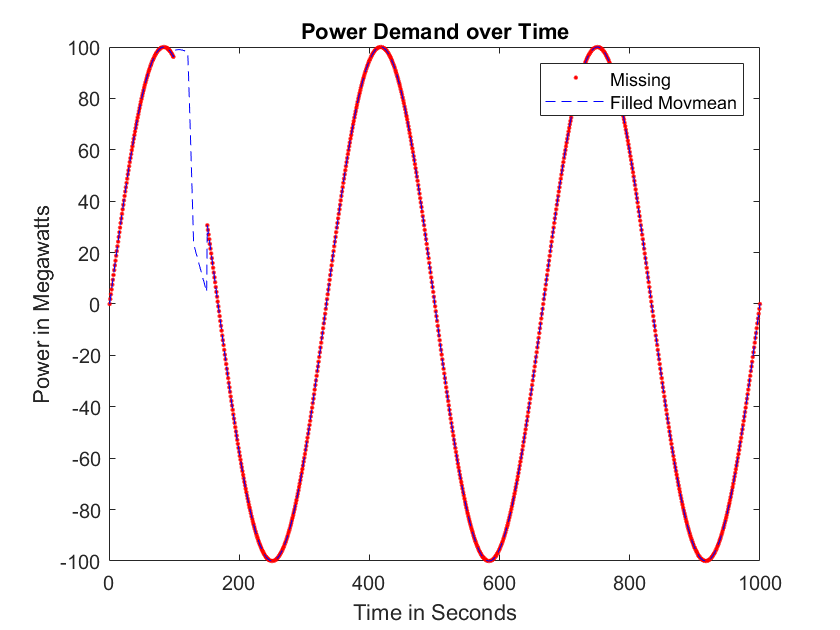

plot(Time, Power_nan, 'r.')
hold on
plot(Time, fill_movmean, 'b--')
xlabel('Time in Seconds')
ylabel('Power in Megawatts')
title('Power Demand over Time')
legend('Missing', 'Filled Movmean');
hold off

### Moving Median

fill_movmedian = fillmissing(Power_nan, 'movmedian', 100);
rmse_movmedian = sqrt(mse(Power, fill_movmedian))

rmse_movmedian = 7.3080

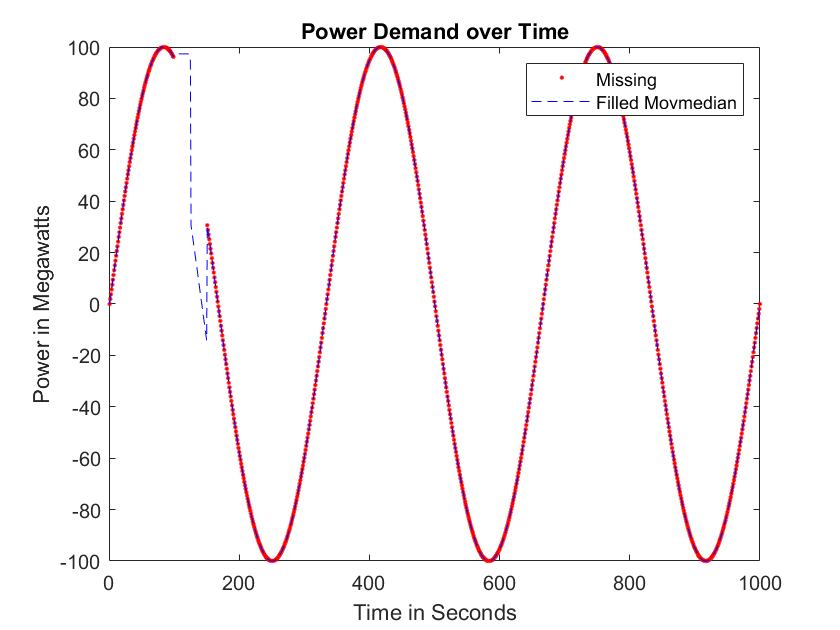

plot(Time, Power_nan, 'r.')
hold on
plot(Time, fill_movmedian, 'b--')
xlabel('Time in Seconds')
ylabel('Power in Megawatts')
title('Power Demand over Time')
legend('Missing', 'Filled Movmedian');
hold off

### Summarize Performance of Imputation Methods

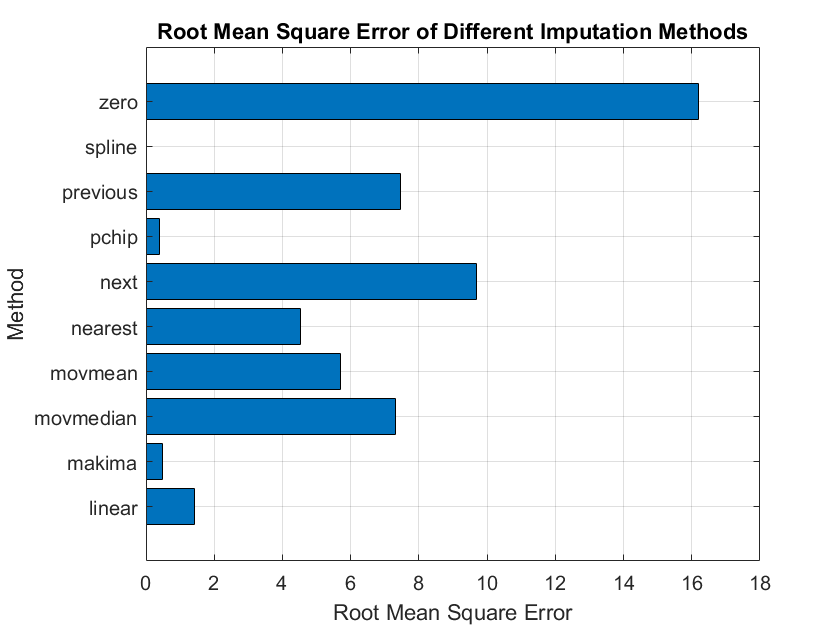

results = [rmse_linear rmse_makima rmse_movmedian rmse_movmean rmse_nearest rmse_next rmse_pchip rmse_previous rmse_spline rmse_zero];
h = barh(results);
set(gca, 'yticklabels',{'linear','makima','movmedian','movmean','nearest','next','pchip','previous','spline','zero'})
title('Root Mean Square Error of Different Imputation Methods')
xlabel('Root Mean Square Error')
ylabel('Method')
grid on